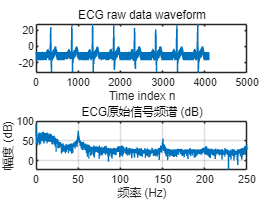

% 用于处理规则数据
%%%%%%%%%%%%%%%%%% --读取数据-- %%%%%%%%%%%%%%%%%%
clear all;
close all;
% 文件路径
filePath = 'C:\Users\hslnb\Documents\Tencent Files\2217574026\FileRecv\定量工程设计方法2\后期作业\心电信号测量\serial_data_raw2000.dat';
% 参数设置
dataLen = 4096;      % 数据点数
fs = 500;            % 采样频率(Hz)
delay = 0;           % 延迟点数
off = 0;             % 偏移量
tmpLen = dataLen + delay + off;
% 读取数据
fid = fopen(filePath, 'r');
if fid == -1
    error('无法打开文件，请检查路径是否正确');
end

%%%%%%%%%%%%%%%%%% --处理数据-- %%%%%%%%%%%%%%%%%%
% 读取原始8位数据（读取双倍长度的8位数据）
tmpOut = fread(fid, tmpLen*2, 'uint8'); 
fclose(fid);

% 初始化16位数据数组
ecgData = zeros(1, dataLen);

% 将两个8位组合成一个16位有符号整数（低位在前，高位在后）
for i = 1 + delay : dataLen + delay
    % 组合低8位和高8位
    combined = tmpOut((i-1)*2 + 1 + off) + tmpOut((i-1)*2 + 2 + off)*256;
    
    % 处理二进制补码（将超过32767的视为负数）
    if combined > 32767
        combined = combined - 65536;
    end
    
    ecgData(i - delay) = combined;
end

%%%%%%%%%%%%%%%%%% --绘制时域波形-- %%%%%%%%%%%%%%%%%%
% 创建时间轴
t = (0:dataLen-1)/fs;
% 绘制时域波形
figure;
subplot(2,1,1);
plot(ecgData); 
title('ECG raw data waveform');
xlabel('Time index n');

%%%%%%%%%%%%%%%%%% --绘制频域波形-- %%%%%%%%%%%%%%%%%%
% ecgData = ecgData / max(abs(ecgData)); % 归一化到[-1, 1]
subplot(2,1,2);
N = length(ecgData);
fft_ecg = abs(fft(ecgData));
freq_axis = (0:N-1)*(fs/N); % 生成0-fs的频率轴(0-500Hz)

plot(freq_axis, 20*log10(fft_ecg+ eps)); % 直接绘制全频谱
title('ECG原始信号频谱 (dB)');
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
xlim([0 250]); % 强制显示0-500Hz
grid on;


dc_index = 1; % 0Hz对应第一个点
original_dc_db = 20*log10(fft_ecg(dc_index));
disp(['原始信号0Hz处幅度(dB): ', num2str(original_dc_db), ' dB']);

原始信号0Hz处幅度(dB): 92.4488 dB



%%%%%%%%%%%%%%%%%% --IIR滤除直流分量-- %%%%%%%%%%%%%%%%%%
a = 0.992; % 极点位置
b = [1, -1]; % 零点在z=1（直流）
a_filter = [1, -a]; % 极点在z=a

% 计算频率响应验证衰减
[h, w] = freqz(b, a_filter, fs, fs);
dc_attenuation = -20*log10(abs(h(1))); % 计算直流衰减(dB)
disp(['直流衰减量：', num2str(dc_attenuation), ' dB']);

直流衰减量：Inf dB


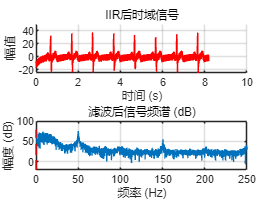


% 应用陷波滤波器
ecg_filtered = filter(b, a_filter, ecgData);

figure;
% 时域对比
subplot(2,1,1);
hold on;
plot(t, ecg_filtered, 'r');
title('IIR后时域信号');
xlabel('时间 (s)');
ylabel('幅值');
grid on;

% 滤波后频谱
fft_filtered = abs(fft(ecg_filtered));
subplot(2,1,2);
plot(freq_axis, 20*log10(fft_filtered(1:N))); 
title('滤波后信号频谱 (dB)');
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
xlim([0 250]);
hold on;
plot([0 0], ylim, 'r--'); % 标记0Hz
grid on;


% 计算频率响应（使用更多点数使曲线平滑）
[h_fine, w_fine] = freqz(b, a_filter, 2048, fs);

% 转换为增益(dB)和相位(度)
gain_dB = 20*log10(abs(h_fine));
phase_deg = unwrap(angle(h_fine)) * 180/pi;

% 计算IIR滤波后信号0Hz处的dB值
filtered_dc_db = 20*log10(fft_filtered(dc_index));
disp(['IIR滤波后0Hz处幅度(dB): ', num2str(filtered_dc_db), ' dB']);

IIR滤波后0Hz处幅度(dB): 62.4399 dB


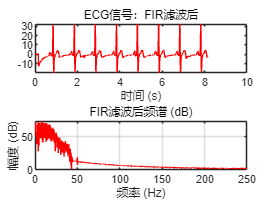



%%%%%%%%%%%%%%%%%% --用Hd进行IIR滤波-- %%%%%%%%%%%%%%%%%%
% 滤波
% filtered_ecg = filter(Hd_IIR, ecgData);
% 
% figure;
% subplot(2,1,1);
% plot(t, filtered_ecg, 'r');
% title('ECG信号：IIR滤波后');
% xlabel('时间 (s)');
% 
% subplot(2,1,2);
% N = length(filtered_ecg);
% fft_filtered = abs(fft(filtered_ecg));
% freq_axis = (0:N-1)*(fs/N);
% plot(freq_axis, 20*log10(fft_filtered), 'r');
% title('IIR滤波后频谱 (dB)');
% xlabel('频率 (Hz)');
% ylabel('幅度 (dB)');                                        
% xlim([0 500]);
% grid on;
%%%%%%%%%%%%%%%%%% --FIR滤除高频噪声-- %%%%%%%%%%%%%%%%%%
% 滤波
filtered_ecg = filter(Hd_FIR2, ecg_filtered);

figure;
subplot(2,1,1);
plot(t, filtered_ecg, 'r');
title('ECG信号：FIR滤波后');
xlabel('时间 (s)');

subplot(2,1,2);
N = length(filtered_ecg);
fft_filtered = abs(fft(filtered_ecg));
freq_axis = (0:N-1)*(fs/N);
plot(freq_axis, 20*log10(fft_filtered), 'r');
title('FIR滤波后频谱 (dB)');
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');                                        
xlim([0 250]);
grid on;


% 计算FIR滤波后信号0Hz处的dB值
fir_filtered_dc_db = 20*log10(fft_filtered(dc_index));
disp(['FIR滤波后0Hz处幅度(dB): ', num2str(fir_filtered_dc_db), ' dB']);

FIR滤波后0Hz处幅度(dB): 61.4493 dB


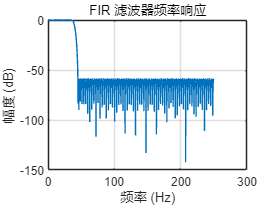


[h_fir, w_fir] = freqz(Hd_FIR2, 2048, fs);
figure;
plot(w_fir, 20*log10(abs(h_fir)));
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
title('FIR 滤波器频率响应');
grid on;